% =========================================================================
% Techno-Economic FFF Print Farm Scheduling Model
% Phase 1: Optimization | Phase 2: Post-Processing Accounting
% Features: Dynamic Variable Bounding & 980g Spool Capacity Limit
% =========================================================================
clear; clc;

%% 1. SETS AND INDICES
num_i = 9; % Number of unique components (1a, 1b, 2a, 2b, 2c, 3a, 3b, 3c, 3d)
num_s = 3; % Number of final products (1, 2, 3)
num_p = 2; % Number of printers (e.g., 2 Bambu P1S)
num_c = 4; % Colors: 1=Blue, 2=Red, 3=White, 4=Yellow

%% 2. PARAMETERS (From Table I)
% Demand for each final assembly
Dem_s = [103; 47; 24]; % e.g., 5 of Prod 1, 3 of Prod 2, 10 of Prod 3

% Bill of Materials (B_is) - Row = Component i, Col = Product s
B_is = zeros(num_i, num_s);
B_is(1,1) = 1;  B_is(2,1) = 1;   % Product 1 uses 1a, 1b
B_is(3,2) = 1;  B_is(4,2) = 1;  B_is(5,2) = 16; % Product 2 uses 2a, 2b, 2c
B_is(6,3) = 1;  B_is(7,3) = 2;  B_is(8,3) = 1;  B_is(9,3) = 1; % Product 3

% Print Times (T_i) in minutes
T_i = [34.68; 7.01; 39.41; 12.1; 0.78; 20.2; 11.83; 11.68; 3.41];

% Footprint Area (Area_i) in mm^2
Area_i = [4277.5; 4277.5; 3818.8; 772.2; 61.3; 3169.9; 2742.6; 955.4; 282.2];

% Material Weight per Color (W_ic) - Row = Component i, Col = Color c
W_ic = zeros(num_i, num_c);
W_ic(1,:) = [3.40, 0, 3.71, 6.08]; % 1a
W_ic(2,:) = [0, 0, 0, 1.76];       % 1b
W_ic(3,:) = [0, 0, 0, 15.34];      % 2a
W_ic(4,:) = [0.27, 0.70, 0.81, 2.07]; % 2b
W_ic(5,:) = [0, 0.14, 0, 0];       % 2c
W_ic(6,:) = [0, 0, 5.45, 0];       % 3a
W_ic(7,:) = [0, 4.54, 0, 0];       % 3b
W_ic(8,:) = [0.23, 0, 1.91, 0.76]; % 3c
W_ic(9,:) = [0, 0, 0, 0.57];       % 3d

% Binary Color Map (K_ic): 1 if weight > 0, else 0
K_ic = W_ic > 0;

% Physical Limits & Costs
Area_max = 65536;       % 256x256 mm bed
Cap_spool = 980;        % Max grams per spool
T_batch = 10;           % Bed prep penalty (min)
T_swap = 2;             % AMS swap penalty (min)
T_tower = 45;           % Prime tower penalty (min)
C_time = 0.03;          % $/min amortized machine cost
C_mat = 0.02;           % $/gram material cost
W_max = 0.05;           % $/min Makespan penalty
alpha = 2;              % Slack variable for packing inefficiencies
M = 10000;              % Big-M

%% 3. PRE-PROCESSING: DERIVED DEMAND & DYNAMIC BOUNDING
% Calculate exact component demand required to satisfy BOM
derived_demand = B_is * Dem_s;

% Calculate total required area and mass for the entire order
total_required_area = sum(derived_demand .* Area_i);
total_required_mass = sum(derived_demand .* sum(W_ic, 2));

% Minimum beds dictated by physical bottlenecks (Eq 16 & 17)
min_beds_area = ceil(total_required_area / Area_max);
min_beds_mass = ceil(total_required_mass / Cap_spool);

% The absolute minimum number of beds the farm MUST use
absolute_min_beds = max(min_beds_area, min_beds_mass);

% Dynamic upper bound for sequential beds per printer (Eq 18)
num_b = ceil((absolute_min_beds + alpha) / num_p);

fprintf('--- Pre-Processing Phase ---\n');

--- Pre-Processing Phase ---


fprintf('Total Parts Required: %d\n', sum(derived_demand));

Total Parts Required: 1172


fprintf('Theoretical Min Beds: %d\n', absolute_min_beds);

Theoretical Min Beds: 22


fprintf('Allocated max beds per printer (num_b): %d\n', num_b);

Allocated max beds per printer (num_b): 12


fprintf('----------------------------\n\n');

----------------------------




%% 4. INITIALIZE OPTIMIZATION PROBLEM
prob = optimproblem('ObjectiveSense', 'minimize');

% Decision Variables
X = optimvar('X', num_i, num_p, num_b, 'Type', 'integer', 'LowerBound', 0);
Y = optimvar('Y', num_p, num_b, 'Type', 'integer', 'LowerBound', 0, 'UpperBound', 1);
R = optimvar('R', num_c, num_p, num_b, 'Type', 'integer', 'LowerBound', 0, 'UpperBound', 1);
Z = optimvar('Z', num_p, num_b, 'Type', 'integer', 'LowerBound', 0, 'UpperBound', 1);
C_bed = optimvar('C_bed', num_p, num_b, 'LowerBound', 0);
C_max = optimvar('C_max', 'LowerBound', 0);

%% 5. PHASE 1: OBJECTIVE FUNCTION (Variable Costs Only)
Z_time = W_max * C_max;
Z_overhead = sum(sum( Y .* (T_batch * C_time) )) + ...
             sum(sum( Z .* (T_tower * C_time) )) + ...
             sum(sum(sum( R .* (T_swap * C_time) )));

prob.Objective = Z_time + Z_overhead;

%% 6. PHASE 1: CONSTRAINTS
% Eq 4: BOM Demand Satisfaction
for i = 1:num_i
    prob.Constraints.(sprintf('Demand_%d', i)) = sum(sum(X(i,:,:))) == derived_demand(i);
end

% Bed Constraints (Loops over Printers and Beds)
for p = 1:num_p
    for b = 1:num_b
        % Eq 5: Area Capacity Limit
        prob.Constraints.(sprintf('Area_%d_%d', p, b)) = ...
            sum(Area_i .* X(:, p, b)) <= Area_max * Y(p, b);
        
        % Eq 6: Mass Spool Capacity Limit (980g constraint)
        for c = 1:num_c
            prob.Constraints.(sprintf('Mass_%d_%d_%d', c, p, b)) = ...
                sum(W_ic(:, c) .* X(:, p, b)) <= Cap_spool;
        end
        
        % Eq 7: Bed Trigger (Big M)
        prob.Constraints.(sprintf('BedTrig_%d_%d', p, b)) = ...
            sum(X(:, p, b)) <= M * Y(p, b);
            
        % Eq 8: Color Trigger (Big M)
        for c = 1:num_c
            prob.Constraints.(sprintf('ColTrig_%d_%d_%d', c, p, b)) = ...
                sum(K_ic(:, c) .* X(:, p, b)) <= M * R(c, p, b);
        end
        
        % Eq 9: Prime Tower Trigger
        prob.Constraints.(sprintf('TowTrig_%d_%d', p, b)) = ...
            sum(R(:, p, b)) - 1 <= M * Z(p, b);
            
        % Eq 12/13: Makespan Definition
        prob.Constraints.(sprintf('Makespan_%d_%d', p, b)) = ...
            C_max >= C_bed(p, b);
            
        % Eq 11: Chronological Time Linking
        active_time = sum(T_i .* X(:, p, b));
        overhead_time = T_batch * Y(p, b) + sum(T_swap * R(:, p, b)) + T_tower * Z(p, b);
        
        if b == 1
            prob.Constraints.(sprintf('Time_%d_%d', p, b)) = ...
                C_bed(p, b) >= active_time + overhead_time;
        else
            % Eq 10: Symmetry Breaking (Must use bed b-1 before bed b)
            prob.Constraints.(sprintf('Sym_%d_%d', p, b)) = ...
                Y(p, b) <= Y(p, b-1);
                
            prob.Constraints.(sprintf('Time_%d_%d', p, b)) = ...
                C_bed(p, b) >= C_bed(p, b-1) + active_time + overhead_time;
        end
    end
end

%% 7. SOLVE THE PROBLEM
disp('Starting Solver...');

Starting Solver...



% Set Max Time AND a Relative Gap Tolerance (e.g., 0.05 = 5% gap)
options = optimoptions('intlinprog', ...
    'Display', 'iter', ...
    'MaxTime', 600, ...
    'RelativeGapTolerance', 0.01); % EARLY STOPPING TRIGGER

% Start the computational timer
solver_tic = tic; 

% Execute the Branch and Bound MILP Solver
[sol, fval, exitflag, output] = solve(prob, 'Options', options);


Solving problem using intlinprog.
Running HiGHS 1.7.1: Copyright (c) 2024 HiGHS under MIT licence terms
Coefficient ranges:
  Matrix [1e-01, 7e+04]
  Cost   [5e-02, 1e+00]
  Bound  [1e+00, 1e+00]
  RHS    [1e+00, 1e+03]
Presolving model
247 rows, 385 cols, 1794 nonzeros  0s
245 rows, 383 cols, 1790 nonzeros  0s

Solving MIP model with:
   245 rows
   383 cols (144 binary, 216 integer, 0 implied int., 23 continuous)
   1790 nonzeros

        Nodes      |    B&B Tree     |            Objective Bounds              |  Dynamic Constraints |       Work      
     Proc. InQueue |  Leaves   Expl. | BestBound       BestSol              Gap |   Cuts   InLp Confl. | LpIters     Time

         0       0         0   0.00%   0               inf                  inf        0      0      0         0     0.0s
 R       0       0         0   0.00%   230.3062711     273.3015          15.73%        0      0      0       403     0.1s
 L       0       0         0   0.00%   249.7020083     270.608           


% Stop the timer and record the duration in seconds
compute_time = toc(solver_tic); 

% Print the final gap achieved
fprintf('Solver stopped with a final optimality gap of: %.2f%%\n', output.absolutegap / fval * 100);

Solver stopped with a final optimality gap of: 0.96%



%% 8. PHASE 2: POST-PROCESSING (COGS ACCOUNTING)
if exitflag > 0
    disp('Optimal Schedule Found!');
    
    % Calculate Z_base (Equation 14)
    % 1. Machine Time Baseline Cost
    base_time_cost = sum(derived_demand .* T_i) * C_time;
    
    % 2. Material Baseline Cost
    base_mat_cost = 0;
    for c = 1:num_c
        base_mat_cost = base_mat_cost + sum(derived_demand .* W_ic(:, c)) * C_mat;
    end
    
    Z_base = base_time_cost + base_mat_cost;
    Z_variable_optimal = fval;
    Total_COGS = Z_variable_optimal + Z_base;
    
    % Display Results
    fprintf('\n===================================\n');
    fprintf('          FINANCIAL COGS           \n');
    fprintf('===================================\n');
    fprintf('PHASE 1: Minimized Variable: $%.2f\n', Z_variable_optimal);
    fprintf('PHASE 2: Baseline Static:    $%.2f\n', Z_base);
    fprintf('-----------------------------------\n');
    fprintf('TOTAL SYSTEM COGS:           $%.2f\n', Total_COGS);
    fprintf('Total Makespan (C_max):      %.1f min (%.2f hrs)\n', sol.C_max, sol.C_max/60);
    fprintf('===================================\n');
else
    disp('Solver failed to find an optimal solution.');
end

Optimal Schedule Found!


          FINANCIAL COGS           


PHASE 1: Minimized Variable: $254.10


PHASE 2: Baseline Static:    $321.07


-----------------------------------


TOTAL SYSTEM COGS:           $575.17


Total Makespan (C_max):      4687.2 min (78.12 hrs)


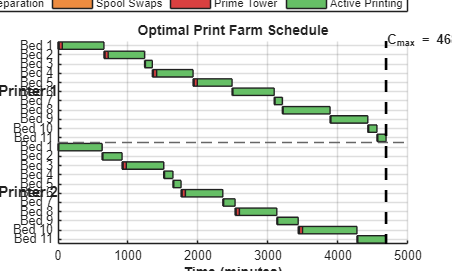


%% 9. GENERATE GANTT CHART VISUALIZATION (CASCADING WATERFALL)
    figure('Name', 'Optimal Print Farm Schedule', 'Color', 'w', 'Position', [100, 100, 1000, 600]);
    hold on; grid on;
    
    % Define distinct colors for visual clarity
    color_batch = [0.93, 0.84, 0.25]; % Yellow
    color_swap  = [0.93, 0.55, 0.25]; % Orange
    color_tower = [0.85, 0.25, 0.25]; % Red
    color_print = [0.40, 0.75, 0.40]; % Green
    
    % Map component indices to their actual names from Table I
    part_names = {'1a', '1b', '2a', '2b', '2c', '3a', '3b', '3c', '3d'};
    
    y_labels = {};
    row_idx = 1; % Tracks the current vertical row for the waterfall effect
    
    % Data structures to dynamically track the row ranges for each printer
    printer_start_row = zeros(num_p, 1);
    printer_end_row = zeros(num_p, 1);
    
    for p = 1:num_p
        current_time = 0; % Start time for this specific printer
        printer_start_row(p) = row_idx; % Record the first row for this printer
        
        for b = 1:num_b
            % Only draw if the bed is actually triggered by the solver
            if round(sol.Y(p,b)) == 1
                
                % 1. Bed Prep Segment
                time_batch = T_batch;
                rectangle('Position', [current_time, row_idx-0.4, time_batch, 0.8], 'FaceColor', color_batch);
                current_time = current_time + time_batch;
                
                % 2. AMS Swap Segment
                time_swaps = sum(round(sol.R(:, p, b))) * T_swap;
                if time_swaps > 0
                    rectangle('Position', [current_time, row_idx-0.4, time_swaps, 0.8], 'FaceColor', color_swap);
                    current_time = current_time + time_swaps;
                end
                
                % 3. Prime Tower Segment
                time_tower = round(sol.Z(p,b)) * T_tower;
                if time_tower > 0
                    rectangle('Position', [current_time, row_idx-0.4, time_tower, 0.8], 'FaceColor', color_tower);
                    current_time = current_time + time_tower;
                end
                
                % 4. Active Print Segment
                time_print = sum(T_i .* round(sol.X(:, p, b)));
                rectangle('Position', [current_time, row_idx-0.4, time_print, 0.8], 'FaceColor', color_print);
                
                % (REMOVED: Part Assignment Text Generation & Plotting)
                
                current_time = current_time + time_print;
                
                % Label the Y-Axis with just the Bed number
                y_labels{row_idx} = sprintf('Bed %d', b); 
                row_idx = row_idx + 1;
            end
        end
        printer_end_row(p) = row_idx - 1; % Record the last row for this printer
    end
    
    total_rows = row_idx - 1;
    
    % Reverse the Y-Axis so it cascades downwards (classic Gantt style)
    ax = gca;
    set(ax, 'YDir', 'reverse');
    
    % Formatting the Chart limits and standard labels
    plot([sol.C_max, sol.C_max], [0, total_rows+1], 'k--', 'LineWidth', 2); % Makespan line
    text(sol.C_max + 2, 0.5, sprintf('C_{max} = %.1f min', sol.C_max), 'FontWeight', 'bold');
    
    ylim([0.5, total_rows + 0.5]);
    yticks(1:total_rows);
    yticklabels(y_labels);
    xlabel('Time (minutes)', 'FontWeight', 'bold');
    title('Optimal Print Farm Schedule', 'FontWeight', 'bold');
    
    % Create custom legend
    h1 = patch([0 0], [0 0], color_batch);
    h2 = patch([0 0], [0 0], color_swap);
    h3 = patch([0 0], [0 0], color_tower);
    h4 = patch([0 0], [0 0], color_print);
    legend([h1, h2, h3, h4], {'Bed Preparation', 'Spool Swaps', 'Prime Tower', 'Active Printing'}, ...
        'Location', 'northoutside', 'Orientation', 'horizontal');
        
    % =========================================================
    % --- NEW: ADVANCED Y-AXIS GROUPING (PRINTER LABELS & LINES) ---
    % =========================================================
    
    yl = ax.YLim;
    xNorm = -0.09; % Negative to push it left of the standard y-axis ticks
    
    for p = 1:num_p
        % Only process if the printer actually utilized at least one bed
        if printer_end_row(p) >= printer_start_row(p)
            % 1. Add grouped "Printer X" Text
            center_y = mean([printer_start_row(p), printer_end_row(p)]);
            
            % Convert center_y to normalized units. 
            % Because YDir is 'reverse', 1 is at the top limit and 0 is at the bottom.
            yCentersNorm = (yl(2) - center_y) / diff(yl);
            
            text(ax, xNorm, yCentersNorm, sprintf('Printer %d', p), ...
                'Units', 'normalized', ...
                'HorizontalAlignment', 'center', ...
                'VerticalAlignment', 'middle', ...
                'FontWeight', 'bold', 'FontSize', 11);
                
            % 2. Draw Separator Lines between printers
            if p < num_p
                sepY = printer_end_row(p) + 0.5;
                if sepY < total_rows % Don't draw at the very bottom edge
                    line(ax.XLim, [sepY sepY], 'Color', [0.4 0.4 0.4], ...
                         'LineStyle', '--', 'LineWidth', 1.2, 'HandleVisibility', 'off');
                end
            end
        end
    end
    
    % Adjust left margin dynamically so the new group labels aren't cut off
    ti = ax.TightInset;
    left_margin = ti(1) + 0.08; % Increase padding
    ax.Position(1) = left_margin;
    
    hold off;

%% 11. GENERATE PRODUCTION SCHEDULE TABLE & SUMMARY
    disp(' ');

    disp('================================================================================================');

    disp('                                   OPTIMIZED PART ASSIGNMENTS                                   ');

                                   OPTIMIZED PART ASSIGNMENTS                                   


    disp('================================================================================================');

    disp(' Printer | Bed | End Time | Prep (m) | Swaps (m) | Tower (m) | Assigned Components            ');

 Printer | Bed | End Time | Prep (m) | Swaps (m) | Tower (m) | Assigned Components            


    disp('---------|-----|----------|----------|-----------|-----------|--------------------------------');

---------|-----|----------|----------|-----------|-----------|--------------------------------



    % Initialize accumulators for the summary footer
    total_prep_time = 0;
    total_swap_time = 0;
    total_tower_time = 0;

    for p = 1:num_p
        current_time = 0; % Track chronological time for this specific printer
        
        for b = 1:num_b
            % Only print rows for beds that were actually used
            if round(sol.Y(p,b)) == 1
                
                % Calculate exact penalties for this bed
                time_batch = T_batch;
                time_swaps = sum(round(sol.R(:, p, b))) * T_swap;
                time_tower = round(sol.Z(p,b)) * T_tower;
                time_print = sum(T_i .* round(sol.X(:, p, b)));
                
                % Add to total accumulators
                total_prep_time = total_prep_time + time_batch;
                total_swap_time = total_swap_time + time_swaps;
                total_tower_time = total_tower_time + time_tower;
                
                % Calculate the exact completion time for this plate
                current_time = current_time + time_batch + time_swaps + time_tower + time_print;
                
                % Extract part assignments
                parts_str = '';
                for i = 1:num_i
                    qty = round(sol.X(i,p,b));
                    if qty > 0
                        parts_str = [parts_str, sprintf('%dx %s, ', qty, part_names{i})];
                    end
                end
                
                % Remove the trailing comma and space
                if ~isempty(parts_str)
                    parts_str = parts_str(1:end-2);
                end
                
                % Print the formatted row to the console
                fprintf('    %d    | %3d | %6.1fm | %6dm | %7dm | %7dm | %s\n', ...
                        p, b, current_time, time_batch, time_swaps, time_tower, parts_str);
            end
        end
    end

    1    |   1 |  656.5m |     10m |       6m |      45m | 10x 1a, 21x 3c, 1x 3d
    1    |   2 | 1237.7m |     10m |       6m |      45m | 15x 1a
    1    |   3 | 1347.8m |     10m |       2m |       0m | 14x 1b
    1    |   4 | 1929.0m |     10m |       6m |      45m | 15x 1a
    1    |   5 | 2487.0m |     10m |       6m |      45m | 12x 1a, 4x 3a
    1    |   6 | 3088.2m |     10m |       2m |       0m | 725x 2c, 2x 3b
    1    |   7 | 3205.3m |     10m |       2m |       0m | 15x 1b
    1    |   8 | 3887.3m |     10m |       2m |       0m | 17x 2a
    1    |   9 | 4425.6m |     10m |       2m |       0m | 2x 1b, 13x 2a
    1    |  10 | 4556.4m |     10m |       2m |       0m | 15x 1b, 4x 3d
    1    |  11 | 4687.2m |     10m |       2m |       0m | 15x 1b, 4x 3d
    2    |   1 |  630.4m |     10m |       2m |       0m | 15x 2a, 8x 3d
    2    |   2 |  914.5m |     10m |       2m |       0m | 23x 3b
    2    |   3 | 1510.8m |     10m |       6m |      45m | 15x 1a, 1x 3c, 1x 3d
    

    
    % --- PRINT THE AGGREGATE SUMMARY FOOTER ---
    disp('------------------------------------------------------------------------------------------------');

------------------------------------------------------------------------------------------------


    fprintf(' TOTAL OVERHEAD PENALTIES :           | %6dm | %7dm | %7dm |\n', total_prep_time, total_swap_time, total_tower_time);

 TOTAL OVERHEAD PENALTIES :           |    220m |      78m |     360m |


    disp('================================================================================================');

    fprintf(' SYSTEM MAKESPAN (C_max)  : %.1f minutes (%.2f hours)\n', sol.C_max, sol.C_max/60);

 SYSTEM MAKESPAN (C_max)  : 4687.2 minutes (78.12 hours)


    fprintf(' TOTAL VARIABLE COST (Z*) : $%.2f\n', Z_variable_optimal); 

 TOTAL VARIABLE COST (Z*) : $254.10


    disp('================================================================================================');